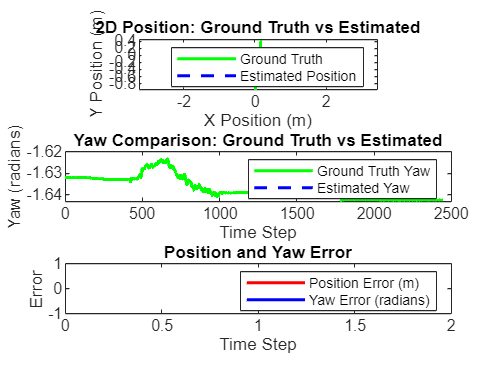

function [X_Est, P_Est, GT] = myEKF(out)
    % Extract Ground Truth signals
    GT_position_val = out.GT_position.signals.values;
    GT_rotation_val = out.GT_rotation.signals.values;
    GT_time_vec = out.GT_time.time;

    % Extract Sensor signals (Values and Time vectors)
    Sensor_ACCEL_val = squeeze(out.Sensor_ACCEL.signals.values);
    Sensor_ACCEL_time = out.Sensor_ACCEL.time;
    Sensor_GYRO_val = squeeze(out.Sensor_GYRO.signals.values);
    Sensor_GYRO_time = out.Sensor_GYRO.time;
    Sensor_ToF1_val = out.Sensor_ToF1.signals.values;
    Sensor_ToF1_time = out.Sensor_ToF1.time;
    
    % Quaternion to Euler (yaw angle)
    eul = quat2eul(GT_rotation_val);
    yaw_ground_truth = eul(:,1);
    
    % Initializing Position
    position_x_gt = GT_position_val(:,1);
    position_y_gt = GT_position_val(:,2);
    time = GT_time_vec;
    
    % Process Noise and Measurement Noise Covariance
    Q = diag([0.01, 0.01, 0.001]); % Process Noise
    R = diag([0.1, 0.1, 0.01]);    % Measurement Noise
    
    % Initialize State Estimation and Covariance
    X_Est = zeros(length(time), 3);
    P_Est = zeros(3, 3, length(time));
    X_Est(1, :) = [position_x_gt(1), position_y_gt(1), yaw_ground_truth(1)];
    P_Est(:,:,1) = eye(3);  % Initial covariance

    for k = 2:length(time)
        dt = time(k) - time(k-1);
        
        % Find the most recent accelerometer and gyroscope data
        idx_accel = find(Sensor_ACCEL_time <= time(k), 1, 'last');
        idx_gyro = find(Sensor_GYRO_time <= time(k), 1, 'last');
        
        % Ensure idx_accel is within bounds of Sensor_ACCEL_val array
        if ~isempty(idx_accel) && idx_accel <= size(Sensor_ACCEL_val, 1)
            accel_x = Sensor_ACCEL_val(idx_accel, 1);
            accel_y = Sensor_ACCEL_val(idx_accel, 2);
            accel_z = Sensor_ACCEL_val(idx_accel, 3);
        else
            accel_x = 0;  % Default value if no valid data is found
            accel_y = 0;
            accel_z = 0;
        end
        
        % Ensure idx_gyro is within bounds of Sensor_GYRO_val array
        if ~isempty(idx_gyro) && idx_gyro <= size(Sensor_GYRO_val, 1)
            gyro_x = Sensor_GYRO_val(idx_gyro, 1);
            gyro_y = Sensor_GYRO_val(idx_gyro, 2);
            gyro_z = Sensor_GYRO_val(idx_gyro, 3);
        else
            gyro_x = 0;  % Default value if no valid data is found
            gyro_y = 0;
            gyro_z = 0;
        end
        
        % Prediction step
        F = [1, 0, -dt * accel_x;
             0, 1, -dt * accel_y;
             0, 0, 1];
         
        B = [dt * cos(X_Est(k-1, 3)), 0;
             dt * sin(X_Est(k-1, 3)), 0;
             0, dt];
        
        U = [accel_x; gyro_z];
        
        X_pred = X_Est(k-1, :)' + B * U;
        P_pred = F * P_Est(:,:,k-1) * F' + Q;

        % **Correcting Z (Measurement Update)**
        % Select the most recent valid ToF measurement
        valid_status = [2, 4]; % Valid status codes for ToF measurements
        sensor_idx = find(ismember(Sensor_ToF1_val(:, 4), valid_status)); % Find valid measurements

        if ~isempty(sensor_idx)
            dist = Sensor_ToF1_val(sensor_idx(end), 1); % Get the most recent valid distance
        else
            dist = NaN; % If no valid data, set to NaN or a default value
        end
        
        % Now Z should contain the measured distance (from ToF) and other state info
        Z = [dist];  % Only distance as the measurement, no position or yaw from GT
        
        % Observation matrix H
        H = [1];
        
        % Kalman Gain and Update
        S = H * P_pred * H' + R;
        K = P_pred * H' / S;
        
        % State Update
        X_Est(k, :) = (X_pred + K * (Z - H * X_pred));
        P_Est(:,:,k) = (eye(3) - K * H) * P_pred;
    end
    
    % Return ground truth for comparison
    GT = [position_x_gt, position_y_gt, yaw_ground_truth];
end

function visualizeResults(X_Est, P_Est, GT)
    figure;
    
    % 2D Position Plot
    subplot(3,1,1);
    plot(GT(:,1), GT(:,2), 'g', 'LineWidth', 1.5); hold on;
    plot(X_Est(:,1), X_Est(:,2), 'b--', 'LineWidth', 1.5);
    legend('Ground Truth', 'Estimated Position');
    xlabel('X Position (m)');
    ylabel('Y Position (m)');
    title('2D Position: Ground Truth vs Estimated');
    axis equal;
    
    % Yaw Plot
    subplot(3,1,2);
    plot(GT(:,3), 'g', 'LineWidth', 1.5); hold on;
    plot(X_Est(:,3), 'b--', 'LineWidth', 1.5);
    legend('Ground Truth Yaw', 'Estimated Yaw');
    xlabel('Time Step');
    ylabel('Yaw (radians)');
    title('Yaw Comparison: Ground Truth vs Estimated');
    
    % Error Plot
    subplot(3,1,3);
    position_error = sqrt((GT(:,1) - X_Est(:,1)).^2 + (GT(:,2) - X_Est(:,2)).^2);
    yaw_error = abs(GT(:,3) - X_Est(:,3));
    plot(position_error, 'r', 'LineWidth', 1.5); hold on;
    plot(yaw_error, 'b', 'LineWidth', 1.5);
    legend('Position Error (m)', 'Yaw Error (radians)');
    xlabel('Time Step');
    ylabel('Error');
    title('Position and Yaw Error');
    
    % Adjust subplot spacing
    set(gcf, 'Position', [100, 100, 800, 600]); % Set the figure size
end

% Load data and run EKF
data = load('trainingData/task1_5.mat');
out = data.out;

[X_Est, P_Est, GT] = myEKF(out);

% Call the visualization function
visualizeResults(X_Est, P_Est, GT);